## First-order ARX model with one delay


$$(q + a_1) y(k) = (b_0 q + b_1) q^{-1}u(k) + e(k+1)$$


% Generate some data
z = tf('z', 1);
% Transfer function
G0 = (z+0.8)/(z*(z-0.9))

G0 =
 
    z + 0.8
  -----------
  z^2 - 0.9 z
 
Sample time: 1 seconds
Discrete-time transfer function.



% Error model
Ge = z/((z-0.9))

Ge =
 
     z
  -------
  z - 0.9
 
Sample time: 1 seconds
Discrete-time transfer function.



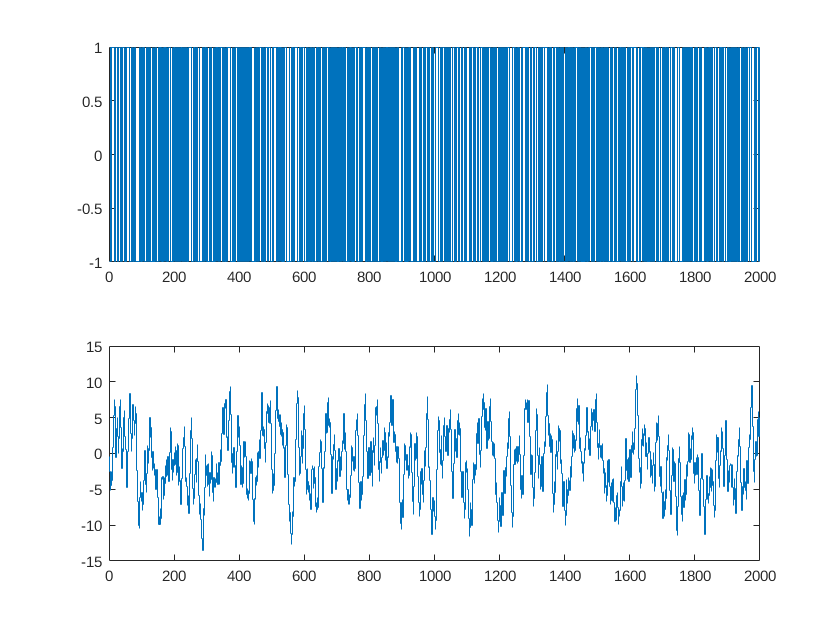

% Input data
u1uv = idinput(4000, 'rbs', [0, 0.6]);
u1 = u1uv(1:2000);
u1v = u1uv(2001:end);

% Perturbation-free output
y10 = lsim(G0, u1);
y10v = lsim(G0, u1v);
% Output with perturbation
e = 0.2*randn(size(u1));
y1 = y10 + lsim(Ge, e);
ev = 0.2*randn(size(u1v));
y1v = y10v + lsim(Ge, ev);

%Plot the data
figure()
subplot(211)
stairs(u1);
subplot(212)
stairs(y1)

### Estimate the parameters

The one-step ahead predictor:


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k) + b_1u(k-1) = \pmatrix{ -y(k) & u(k) & u(k-1)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


The residual vector:


$$\epsilon = y - \Phi\theta$$


Phi = cat(2, -y1(2:end-1), u1(2:end-1), u1(1:end-2));
y = y1(3:end);
theta1 = Phi\y

theta1 =    -0.9001
    1.0048
    0.8023


display(sprintf('a_1 = %f', theta1(1)))

a_1 = -0.900131


display(sprintf('b_0 = %f', theta1(2)))

b_0 = 1.004768


fprintf('b_1 = %f\n', theta1(3))

b_1 = 0.802281


G11 = (theta1(2)*z + theta1(3))/(z*(z+theta1(1)))

G11 =
 
  1.005 z + 0.8023
  ----------------
   z^2 - 0.9001 z
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Fitting the wrong model


$$(q+a_1)y(k) = (b_0q + b_1)u(k) + e(k+1)$$


with one-step ahead predictor


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k+1) + b_1u(k) = \pmatrix{ -y(k) & u(k+1) & u(k)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


Phi = [-y1(1:end-1), u1(2:end), u1(1:end-1) ];
y = y1(2:end);
theta2= Phi\y

theta2 =    -0.9460
   -0.1867
    1.3202


display(sprintf('a_1 = %f', theta2(1)))

a_1 = -0.946029


display(sprintf('b_0 = %f', theta2(2)))

b_0 = -0.186668


display(fprintf('b_1 = %f\n', theta2(3)))

b_1 = 1.320249
    15



G12 = (theta2(2)*z + theta2(3))/(z+theta2(1))

G12 =
 
  -0.1867 z + 1.32
  ----------------
     z - 0.946
 
Sample time: 1 seconds
Discrete-time transfer function.



## Overparameterized model

Phi = [-y1(2:end-1), -y1(1:end-2), u1(2:end-1), u1(1:end-2) ];
y = y1(3:end);
theta3= Phi\y

theta3 =    -0.9120
    0.0104
    1.0034
    0.7823


display(sprintf('a_1 = %f', theta3(1)))

a_1 = -0.912003


display(sprintf('a_2 = %f', theta3(2)))

a_2 = 0.010376


display(sprintf('b_0 = %f', theta3(3)))

b_0 = 1.003361


display(fprintf('b_1 = %f\n', theta3(4)))

b_1 = 0.782269
    15



G13 = (theta3(3)*z + theta3(4))/(z^2+theta3(1)*z + theta3(2))

G13 =
 
     1.003 z + 0.7823
  -----------------------
  z^2 - 0.912 z + 0.01038
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Compare the models

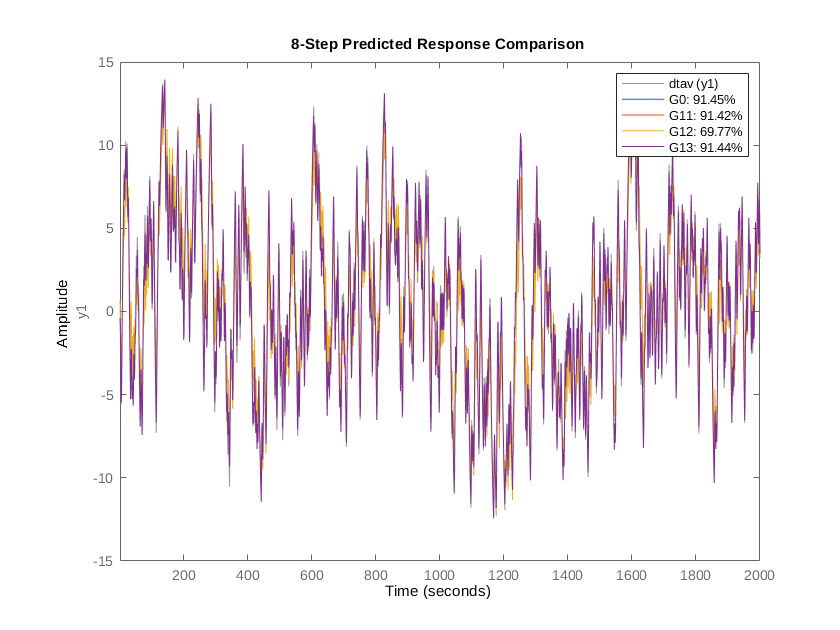

dta = iddata(y1, u1, 1);
dtav = iddata(y1v, u1v, 1);
figure
compare(dtav, G0, G11, G12,G13,  8)

Residual analysis, using ARX models estimated with the sysid toolbox.

G11a = arx(dta, [1, 2, 1]) % True model order

G11a =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9013 z^-1                           
                                                   
  B(z) = 1.002 z^-1 + 0.7966 z^-2                  
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=1
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "dta".   
Fit to estimation data: 95.66% (prediction focus)
FPE: 0.04061, MSE: 0.04041                       


G12a = arx(dta, [1, 2, 0]) % Wrong model order

G12a =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9457 z^-1                           
                                                   
  B(z) = -0.1748 + 1.347 z^-1                      
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=0
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "dta".   
Fit to estimation data: 84.44% (prediction focus)
FPE: 0.5219, MSE: 0.5198                         


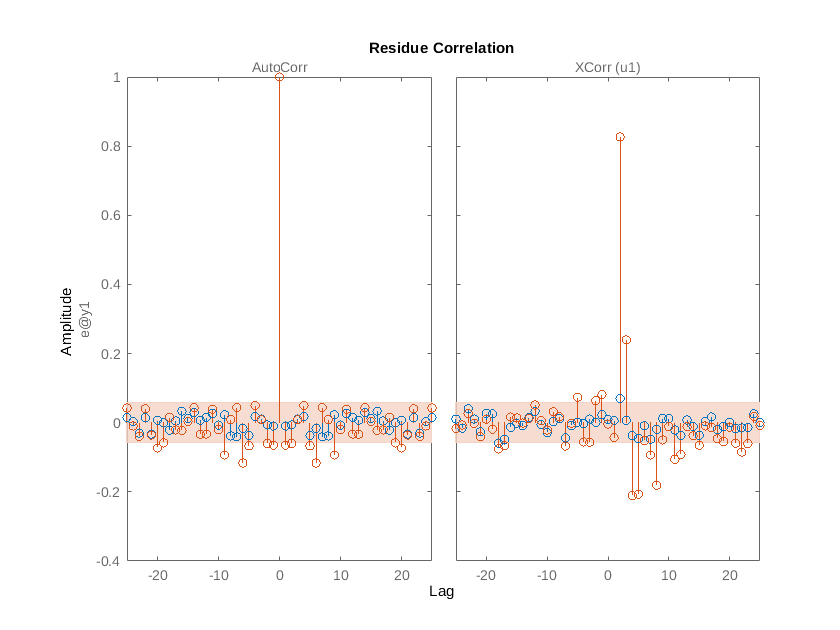

figure
resid(dtav, G11a, G12a)

G11a